% Análise FFT Simplificada - TDAH vs Controle (Feminino)
% Casos mais discrepantes plotados juntos

clear; clc; close all;

% Carregar dados
load('FC.mat');    % Controles femininos
load('FADHD.mat'); % TDAH femininos

% Parâmetros
fs = 256;  % Frequência de amostragem
tarefa = 1;  % Eyes open baseline (Cz, F4, 30s)

% Extrair dados
controle_dado = FC{tarefa};
adhd_dado = FADHD{tarefa};
adhd_dado(7,:,:) = []; % Remove sujeito 7 corrompido(info do dataset)

% Encontrar casos mais discrepantes
fprintf('Buscando casos mais discrepantes...\n');

Buscando casos mais discrepantes...


max_diff = 0;
melhor_controle = 1;
melhor_adhd = 1;
melhor_canal = 1;

for canal = 1:2  % 2 canais: Cz, F4
    for i = 1:size(controle_dado,1)
        for j = 1:size(adhd_dado,1)
            % Sinais
            si_controle = squeeze(controle_dado(i,:,canal));
            si_adhd = squeeze(adhd_dado(j,:,canal));
            
            % FFT simples
            fft_controle = abs(fft(si_controle));
            fft_adhd = abs(fft(si_adhd));
            
            % Diferença (1-50 Hz)
            freq_idx = round(length(fft_controle)/2);
            diff = sum(abs(fft_adhd(1:freq_idx) - fft_controle(1:freq_idx)));
            
            if diff > max_diff
                max_diff = diff;
                melhor_controle = i;
                melhor_adhd = j;
                melhor_canal = canal;
            end
        end
    end
end

% Extrair os melhores casos
si_controle = squeeze(controle_dado(melhor_controle,:,melhor_canal));
si_adhd = squeeze(adhd_dado(melhor_adhd,:,melhor_canal));

% Preparar dados para plots
t = (0:length(si_controle)-1)/fs;  % Tempo
N = length(si_controle);
freq = (0:N/2-1)*(fs/N);  % Frequências

% FFT
fft_controle = abs(fft(si_controle));
fft_adhd = abs(fft(si_adhd));
fft_controle = fft_controle(1:N/2);  % Apenas frequências positivas
fft_adhd = fft_adhd(1:N/2);

% Nomes dos canais
canal_nome = {'Cz', 'F4'};

fprintf('Caso mais discrepante:\n');

Caso mais discrepante:


fprintf('Controle: Sujeito %d, Canal %s\n', melhor_controle, canal_nome{melhor_canal});

Controle: Sujeito 2, Canal Cz


fprintf('TDAH: Sujeito %d, Canal %s\n', melhor_adhd, canal_nome{melhor_canal});

TDAH: Sujeito 2, Canal Cz


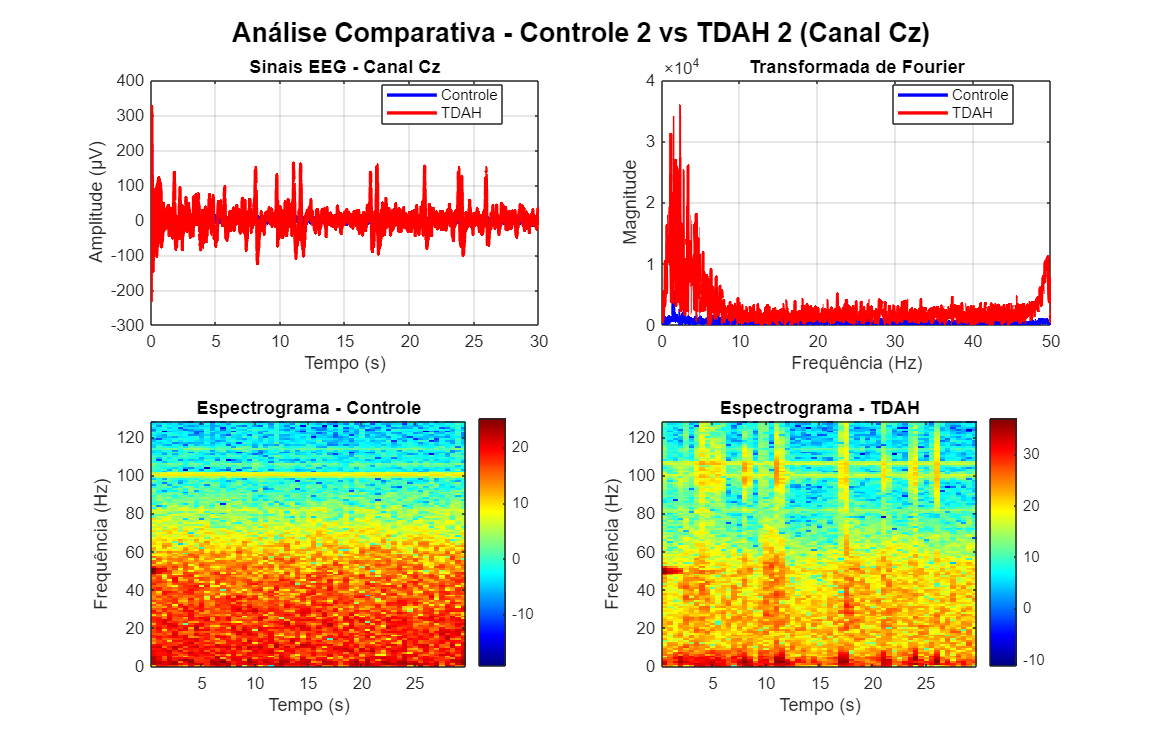


% PLOTS
figure('Position', [50, 50, 1400, 900]);

% 1. Sinal no tempo
subplot(2,2,1);
plot(t, si_controle, 'b-', 'LineWidth', 2, 'DisplayName', 'Controle');
hold on;
plot(t, si_adhd, 'r-', 'LineWidth', 2, 'DisplayName', 'TDAH');
xlabel('Tempo (s)');
ylabel('Amplitude (μV)');
title(sprintf('Sinais EEG - Canal %s', canal_nome{melhor_canal}));
legend('Location', 'best');
grid on;

% 2. FFT - Domínio da frequência
subplot(2,2,2);
plot(freq, fft_controle, 'b-', 'LineWidth', 2, 'DisplayName', 'Controle');
hold on;
plot(freq, fft_adhd, 'r-', 'LineWidth', 2, 'DisplayName', 'TDAH');
xlabel('Frequência (Hz)');
ylabel('Magnitude');
title('Transformada de Fourier');
legend('Location', 'best');
grid on;
xlim([0 50]);  % Foco em 0-50 Hz

% 3. Espectrograma - Controle
subplot(2,2,3);
window = 256;  % Janela para espectrograma
overlap = 128; % Sobreposição
[S_controle, F, T] = spectrogram(si_controle, window, overlap, [], fs);
imagesc(T, F, 10*log10(abs(S_controle)));
axis xy;
xlabel('Tempo (s)');
ylabel('Frequência (Hz)');
title('Espectrograma - Controle');
colorbar;
ylim([0 50]);
colormap('jet');

% 4. Espectrograma - TDAH
subplot(2,2,4);
[S_adhd, F, T] = spectrogram(si_adhd, window, overlap, [], fs);
imagesc(T, F, 10*log10(abs(S_adhd)));
axis xy;
xlabel('Tempo (s)');
ylabel('Frequência (Hz)');
title('Espectrograma - TDAH');
colorbar;
ylim([0 50]);
colormap('jet');

% Título geral
sgtitle(sprintf('Análise Comparativa - Controle %d vs TDAH %d (Canal %s)', ...
        melhor_controle, melhor_adhd, canal_nome{melhor_canal}), ...
        'FontSize', 16, 'FontWeight', 'bold');


% Análise rápida das principais faixas
fprintf('\nAnálise das faixas de frequência:\n');


Análise das faixas de frequência:


faixas = {'Delta (0.5-4 Hz)', 'Theta (4-8 Hz)', 'Alpha (8-12 Hz)', 'Beta (12-30 Hz)'};
limites = [0.5 4; 4 8; 8 12; 12 30];

for i = 1:4
    idx = freq >= limites(i,1) & freq <= limites(i,2);
    power_controle = sum(fft_controle(idx).^2);
    power_adhd = sum(fft_adhd(idx).^2);
    diff_pct = ((power_adhd - power_controle) / power_controle) * 100;
    fprintf('%s: %.1f%% diferença\n', faixas{i}, diff_pct);
end

Delta (0.5-4 Hz): 13762.5% diferença
Theta (4-8 Hz): 8170.3% diferença
Alpha (8-12 Hz): 598.2% diferença
Beta (12-30 Hz): 845.1% diferença
